%% Functions
fc = FunctionCollector;

%% Constants
mu   = 398600.4418;          % [km^3/s^2]
Re   = 6378.1363;            % [km]
J2   = 1.08262668e-3;        % [-]
we   = 7.2921159e-5;         % [rad/s] Earth rotation (sidereal)

%% Assignment assumptions
Omega = deg2rad(0);
omega = deg2rad(0);
nu0   = deg2rad(0);       % true anomaly at t0

Defining Constants and Values for the functions

% Example initial elements (radians). Assignment says ω=Ω=ν=0°
a = 7000;                         % km  (pick any bound, elliptical orbit)
e = 0.01;
i = deg2rad(51.6);                % can be anything for 1a

t0 = 0;                           % s
n  = sqrt(mu/a^3);
T  = 2*pi/n;                      % one period
tf = 2*T;                         % propagate 2 orbits just to test
dt = 60;                          % reasonable step for 1a


Choose dt according to weakest chain in the OD

1b) SSO inclination (hp=550 km, e=0.01), propagate 30 revs

Re  = 6378.1363;                % km
J2  = 1.08262668e-3;            % -
year_sec = 365.2422*86400;      % s
Omega_dot_target = 2*pi/year_sec; % rad/s (sun-synchronous)

% Given orbit parameters
hp = 550;                       % km (perigee height)
e  = 0.01;
rp = Re + hp;                   % km
a  = rp/(1 - e);                % km
p  = a*(1 - e^2);
n  = sqrt(mu/a^3);              % rad/s

% SSO inclination from J2 nodal regression: dΩ/dt = -(3/2) J2 n (Re/p)^2 cos(i)
cosi = -Omega_dot_target / (1.5*J2*n*(Re/p)^2);
i    = acos(max(-1,min(1,cosi)));  % radians (clamped)

% Assignment angles
Omega = 0; omega = 0; nu0 = 0;

% Propagate 30 orbits
T  = 2*pi/n; 
orbits = 30;
t0 = 0; tf = orbits*T; 
dt = 60;

Run 1b)

[t_vec, R_newton_unperturbed, V_newton_unperturbed] = fc.propagate_orbit_keplar_newton(a,e,i,Omega,omega,nu0,mu,t0,tf,dt,0,0);

1c)     

Now Plotting the Orbit. First for the plot itself a few variables like earth itself and so on...

Re = 6378.1363;            % km
we = 7.2921159e-5;         % rad/s (Earth rotation rate)
theta_g0 = 0;              % GMST at t0 (assume 0 for assignment)
t0 = t_vec(1);

Now for the plot itself:

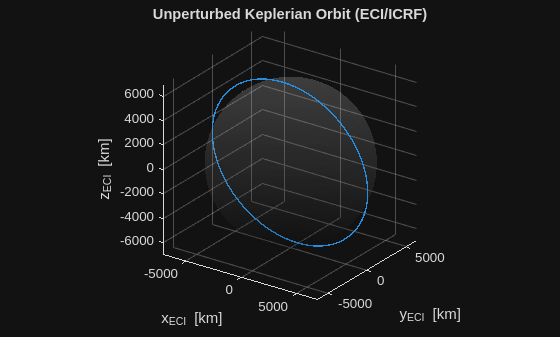

figure('Name','3D Orbit (ECI)');
plot3(R_newton_unperturbed(:,1), R_newton_unperturbed(:,2), R_newton_unperturbed(:,3), 'LineWidth', 1.0); hold on; grid on; axis equal;
% Draw a translucent Earth
[fX,fY,fZ] = sphere(80);
surf(Re*fX, Re*fY, Re*fZ, 'FaceAlpha', 0.1, 'EdgeColor', 'none'); colormap gray;
xlabel('x_{ECI} [km]'); ylabel('y_{ECI} [km]'); zlabel('z_{ECI} [km]');
title('Unperturbed Keplerian Orbit (ECI/ICRF)');
view(35,25);

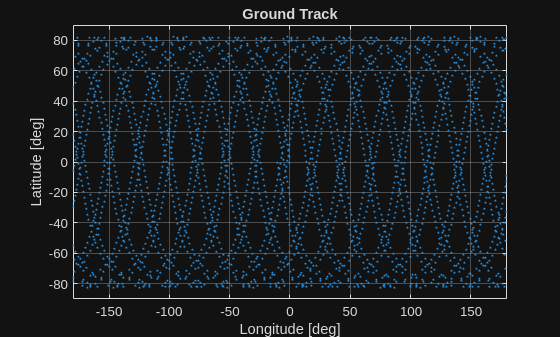


% -------- Ground Track --------
[lat_deg_newton_unperturbed, lon_deg_newton_unperturbed] = fc.convert_eci2lla(R_newton_unperturbed, t_vec, we, theta_g0);

% Wrap longitudes to [-180,180]
lon_deg_newton_unperturbed = mod(lon_deg_newton_unperturbed + 180, 360) - 180;

figure('Name','Ground Track');
plot(lon_deg_newton_unperturbed, lat_deg_newton_unperturbed, '.', 'MarkerSize', 4); grid on;
xlim([-180 180]); ylim([-90 90]);
xlabel('Longitude [deg]'); ylabel('Latitude [deg]');
title('Ground Track');

2) Pertubated orbit propagation

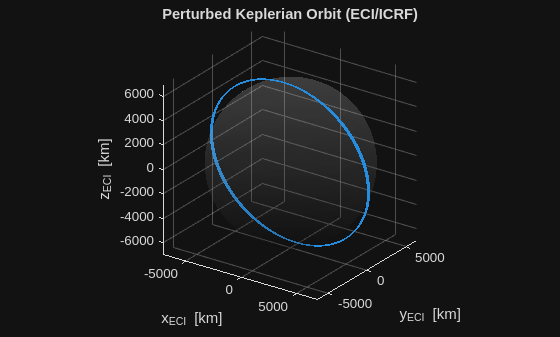

[t_vec, R_newton_perturbed, V_newton_perturbed] = fc.propagate_orbit_keplar_newton(a,e,i,Omega,omega,nu0,mu,t0,tf,dt,Re,J2);

figure('Name','3D Orbit (ECI)');
plot3(R_newton_perturbed(:,1), R_newton_perturbed(:,2), R_newton_perturbed(:,3), 'LineWidth', 1.0); hold on; grid on; axis equal;
% Draw a translucent Earth
[fX,fY,fZ] = sphere(80);
surf(Re*fX, Re*fY, Re*fZ, 'FaceAlpha', 0.1, 'EdgeColor', 'none'); colormap gray;
xlabel('x_{ECI} [km]'); ylabel('y_{ECI} [km]'); zlabel('z_{ECI} [km]');
title('Perturbed Keplerian Orbit (ECI/ICRF)');
view(35,25);

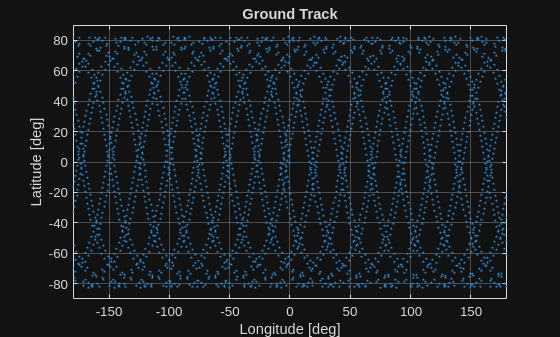


% -------- Ground Track --------
[lat_deg_newton_perturbed, lon_deg_newton_perturbed] = fc.convert_eci2lla(R_newton_perturbed, t_vec, we, theta_g0);

% Wrap longitudes to [-180,180]
lon_deg_newton_perturbed = mod(lon_deg_newton_perturbed + 180, 360) - 180;

figure('Name','Ground Track');
plot(lon_deg_newton_perturbed, lat_deg_newton_perturbed, '.', 'MarkerSize', 4); grid on;
xlim([-180 180]); ylim([-90 90]);
xlabel('Longitude [deg]'); ylabel('Latitude [deg]');
title('Ground Track');

3b) Propagating the orbit using the Orbit EoMs

% Convert keplar elements to position and velocity vectors
[rr0, vv0] = fc.convert_kep2car(a, e, i, Omega, omega, nu0, mu);

%Propagate unperturbed orbit EoM
[t_vec, R_rk4_unpertubred, V_rk4_unperturbed] = fc.propagate_orbit_EoM_rk4(rr0, vv0, t0, tf, dt, mu, 0, 0);

3c) Now with J2 for a pertubed orbit

%Propagate perturbed orbit EoM
[t_vec, R_rk4_perturbed, V_rk4_perturbed] = fc.propagate_orbit_EoM_rk4(rr0, vv0, t0, tf, dt, mu, Re, J2);

4a)

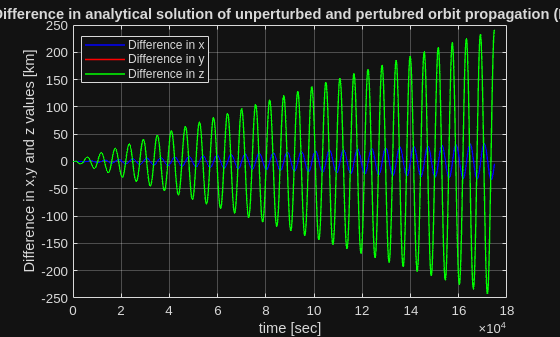

% Plot comparison of newton method between the unperturbed and perturbed orbit
comparison_analytical_perturbed_unperturbed = R_newton_perturbed - R_newton_unperturbed;

figure('Name','Difference in analytical solution of unperturbed and pertubred orbit');
plot(t_vec, comparison_analytical_perturbed_unperturbed(:,1), 'b', 'LineWidth', 1.0); hold on; grid on;
plot(t_vec, comparison_analytical_perturbed_unperturbed(:,2), 'r', 'LineWidth', 1.0); 
plot(t_vec, comparison_analytical_perturbed_unperturbed(:,2), 'g', 'LineWidth', 1.0); 
legend('Difference in x','Difference in y', 'Difference in z','Location','best');
xlabel('time [sec]'); ylabel('Difference values [km]'); hold off;
title('Difference in analytical solution of unperturbed and pertubred orbit propagation (ECI)')

4b)

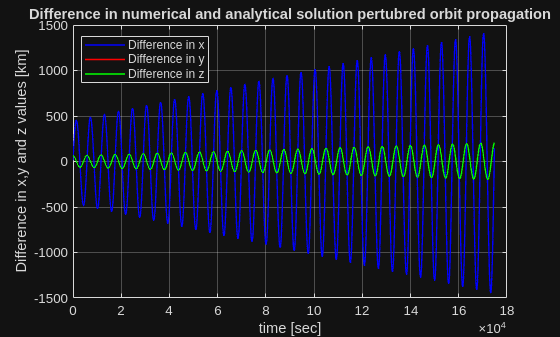

% Plot comparison of perturbed orbit between newton and rk4 method
comparison_analytical_rk4 = R_newton_perturbed - R_rk4_perturbed;

figure('Name','Difference in numerical and analytical solution pertubred orbit propagation');
plot(t_vec, comparison_analytical_rk4(:,1), 'b', 'LineWidth', 1.0); hold on; grid on;
plot(t_vec, comparison_analytical_rk4(:,2), 'r', 'LineWidth', 1.0); 
plot(t_vec, comparison_analytical_rk4(:,2), 'g', 'LineWidth', 1.0); 
legend('Difference in x','Difference in y', 'Difference in z','Location','best');
xlabel('time [sec]'); ylabel('Difference values [km]'); hold off;
title('Difference in numerical and analytical solution pertubred orbit propagation')